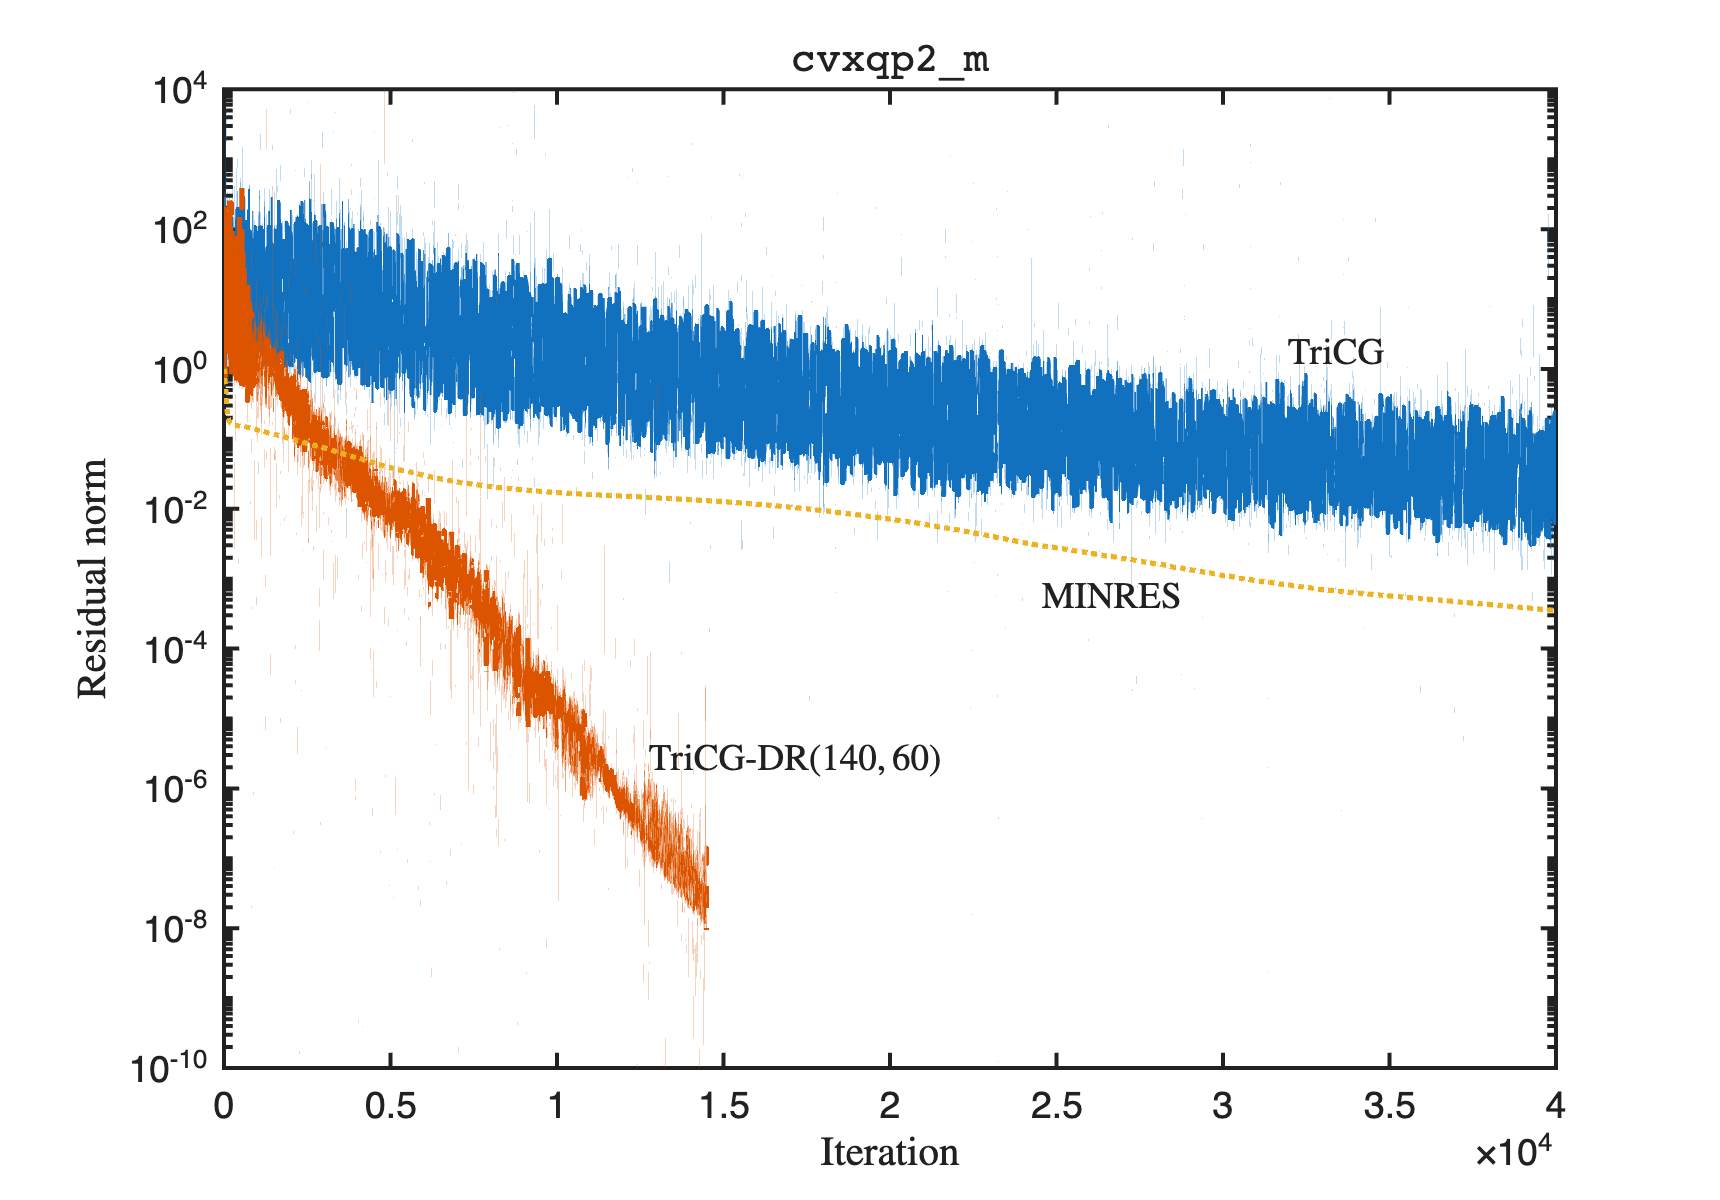

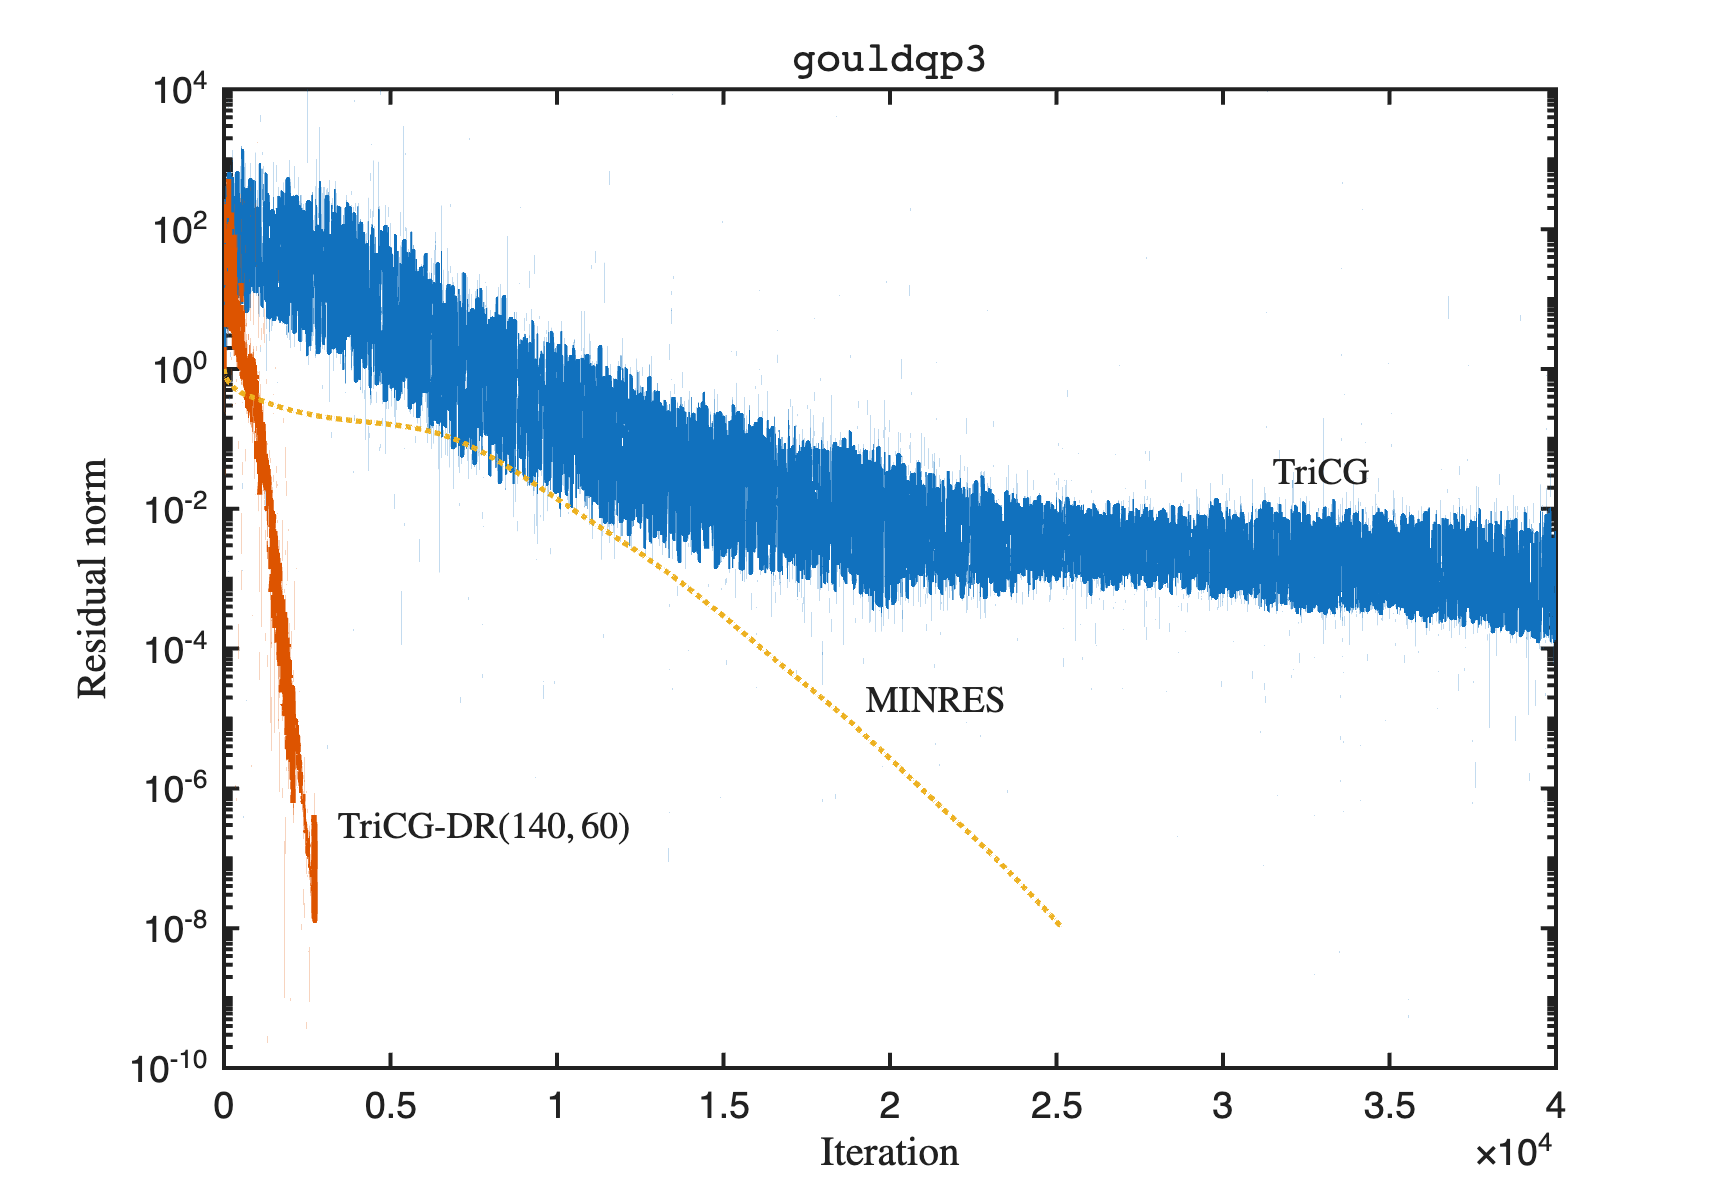

clc; close all; clearvars;

mats = {'cvxqp2_m', 'gouldqp3'};

exres = true;
tol = 1e-8;

stol = 1e-10;
k = 60;
p = k + 80;
maxcycle = 10;
maxit = 40000;

pos1 = [0.7387 0.6841 0.0903 0.04874; 0.7299 0.584 0.0903 0.04874];
pos2 = [0.596 0.4805 0.09611 0.04874; 0.4934 0.3937 0.1138 0.04874];
pos3 = [0.367 0.3132 0.1676 0.08079; 0.1867 0.2564 0.1676 0.08079];
texts = {'TriCG', 'MINRES', sprintf('TriCG-DR$(%d,%d)$', p, k)};

for i = 1:length(mats)
    mat = mats{i};
    load("mats/" + mat + "_iter_5.mat");

    [m, n] = size(A);

    dM = decomposition(M, 'chol');
    dN = decomposition(N, 'chol');
    Mfunc = @(x, t) Mopertor(M, dM, x, t);
    Nfunc = @(x, t) Mopertor(N, dN, x, t);

    K = [M, A; A', -N];
    pre = @(x, t) [Mfunc(x(1:m), t); Nfunc(x(m+1:end), t)];

    nf = sqrt(b'*Mfunc(b, 2) + c'*Nfunc(c, 2));
    b = b / nf;
    c = c / nf;

    [~, ~, ~, tricg_res] = tricg(A, b, c, Mfunc, Nfunc, tol, maxit, exres=exres);
    [~, ~, ~, tricgdr_res] = tricgdr(A, b, c, Mfunc, Nfunc, k, p, tol, ...
        maxcycle, maxit=maxit, stol=stol, exres=exres);

    [~, ~, minres_res] = minres(K, [b; c], pre, tol, maxit, exres=exres);


    default_properties = {'defaultAxesFontSize', 'defaultAxesLineWidth', ...
        'defaultLineLineWidth'};

    default_vals = {14, 1.5, 2};
    set(0, default_properties, default_vals);

    figure(Position=[180 120 860 600]);

    p1 = semilogy(0:length(tricg_res)-1, tricg_res, LineStyle='-');
    hold on;
    p2 = semilogy(0:length(tricgdr_res)-1, tricgdr_res, LineStyle='--');
    p3 = semilogy(0:length(minres_res)-1, minres_res, LineStyle=':');
    hold off;

    title_name = replace(mat, '_', '\_');
    title(sprintf('\\texttt{%s}', title_name), Interpreter='latex', FontSize=18);

    xlabel('Iteration', Interpreter='latex', FontSize=18);
    ylabel('Residual norm', Interpreter='latex', FontSize=18);
    % legend([p1, p3, p2], {'TriCG', 'MINRES', sprintf('TriCG-DR$(%d,%d)\\,$', p, k)}, ...
    %     Location='northeast', Interpreter='latex', FontSize=14);
    annotation("textbox", pos1(i, :), "String", texts{1}, ...
                "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
    annotation("textbox", pos2(i, :), "String", texts{2}, ...
                "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");
    annotation("textbox", pos3(i, :), "String", texts{3}, ...
                "FontSize", 14, "LineStyle", "none", "Interpreter", "latex");

    exportgraphics(gcf, sprintf('figs/fig3_%s.pdf', mat), Resolution=600);
end